**Linear Support Vector Machine - Soft Margins**

Find the separating hyperplane for the data set given by solving the dual problem (5) with C = 10. What is the value of λi corresponding to the misclassified points?

close all;
clear;
clc;
matlab.lang.OnOffSwitchState = 1;

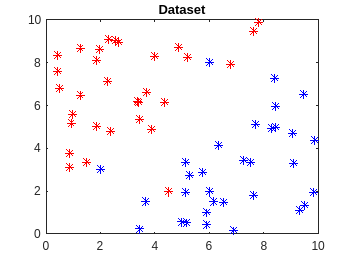

A = [0.4952    6.8088
    2.6505    8.9590
    3.4403    5.3366
    3.4010    6.1624
    5.2153    8.2529
    7.6393    9.4764
    1.5041    3.3370
    3.9855    8.3138
    1.8500    5.0079
    1.2631    8.6463
    3.8957    4.9014
    1.9751    8.6199
    1.2565    6.4558
    4.3732    6.1261
    0.4297    8.3551
    3.6931    6.6134
    7.8164    9.8767
    4.8561    8.7376
    6.7750    7.9386
    2.3734    4.7740
    0.8746    3.0892
    2.3088    9.0919
    2.5520    9.0469
    3.3773    6.1886
    0.8690    3.7550
    1.8738    8.1053
    0.9469    5.1476
    0.9718    5.5951
    0.4309    7.5763
    2.2699    7.1371
    4.5000    2.0000];

B = [7.2450    3.4422
    7.7030    5.0965
    5.7670    2.8791
    3.6610    1.5002
    9.4633    6.5084
    9.8221    1.9383
    8.2874    4.9380
    5.9078    0.4489
    4.9810    0.5962
    5.1516    0.5319
    8.4363    5.9467
    8.4240    4.9696
    7.6240    1.7988
    3.4473    0.2725
    9.0528    4.7106
    9.1046    3.2798
    6.9110    0.1745
    5.1235    3.3181
    7.5051    3.3392
    6.3283    4.1555
    6.1585    1.5058
    8.3827    7.2617
    5.2841    2.7510
    5.1412    1.9314
    6.0290    1.9818
    5.8863    1.0087
    9.5110    1.3298
    9.3170    1.0890
    6.5170    1.4606
    9.8621    4.3674
    6.0000    8.0000
    2.0000    3.0000];

plot(A(:,1),A(:,2), 'r*',B(:,1),B(:,2), 'b*');
title('Dataset');

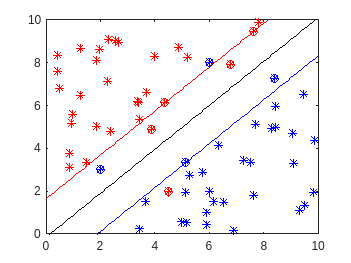

% Set the environment values
nA = size(A,1);
nB = size(B,1);

% Training set
T = [A;B];

C = 10;
y = [ones(nA,1);-ones(nB,1)];
l = length(y);

% Set Q
Q = zeros(l,l);

for i = 1:l
    for j = 1:l
        Q(i,j) = y(i)*y(j)*T(i,:)*T(j,:)';
    end 
end 

f = -ones(l,1);
lb = zeros(l,1);
ub = C*ones(l,1);

% Set the problem
options = optimset('LargeScale', 'off', 'Display', 'off');
lambda = quadprog(Q,f,[],[],y',0, lb,ub, [], options);

% Set W
w = zeros(2,1);
for i = 1:l
    w = w + lambda(i)*y(i)*T(i,:)';
end

% Set b
indicator = find((lambda > 1e-3) & (lambda <= C-1e-3));
i = indicator(1);
b = 1/y(i) - w'*T(i,:)';

% Plot the hyperplane optimize 
x = 0:0.1:10;
u = (-w(1)/w(2)).*x - b/w(2);
v = (-w(1)/w(2)).*x + (1-b)/w(2);
vv = (-w(1)/w(2)).*x + (-1-b)/w(2);
 
plot(A(:,1), A(:,2), 'r*' ,B(:,1), B(:,2), 'b*', ...
     x, u,'k-', x,v, 'r-', x,vv, 'b-');

% Plot the support Points
support = find(lambda > 1e-3);
support_A = support(support <= nA);
support_B = support(support > nA)-nA;

hold on
plot(A(support_A,1), A(support_A,2), 'ro' ,B(support_B,1), B(support_B,2), 'bo');
xlim([0 10]);
ylim([0 10]);
hold off


fprintf('Lambda Values \n Support Points A');

Lambda Values 
 Support Points A

fprintf('%0.2f \n', lambda(support_A));

5.01 
10.00 
1.40 
10.00 
10.00 



fprintf(' Support Points B');

 Support Points B

fprintf('%0.2f \n', lambda(support_B));

0.00 
0.00 
10.00 
0.00 
